clc;
clear;
%% Load the default options:
% These options control options such as the original sampling frequency of
% the data, the sampling frequency for the derived features and whether the
% mex code should be used for the Viterbi decoding:
springer_options = default_Springer_HSMM_options;

%% Load the audio data and the annotations:
% These are 6 example PCG recordings, downsampled to 1000 Hz, with
% annotations of the R-peak and end-T-wave positions.
load('example_data.mat');

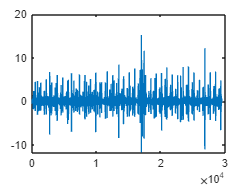

example_data.example_audio_data{1};
plot(ans);


%% Split the data into train and test sets:
% Select the 5 recordings for training and a sixth for testing:
training_indices = (1:300);
train_recordings = example_data.example_audio_data(training_indices);
train_annotations = example_data.example_annotations(training_indices,:);

test_index = (1:792);
test_recordings = example_data.example_audio_data(test_index);
test_annotations = example_data.example_annotations(test_index,:);

fs = 1000;
%% Train the HMM:
[B_matrix, pi_vector, total_obs_distribution] = trainSpringerSegmentationAlgorithm(train_recordings,train_annotations,springer_options.audio_Fs, false);

%Run the HMM on an unseen test recording:
%And display the resulting segmentation

%Number of PCG recordings
numPCGs = length(test_recordings);

counter = 1; %Dummy parameter

%Finding recordings that produce errors and skips them
for PCGi = 1:numPCGs
    try
         [assigned_states]        = runSpringerSegmentationAlgorithm(test_recordings{PCGi}, springer_options.audio_Fs, B_matrix, pi_vector, total_obs_distribution, false);
         asssigned_states{:,PCGi} = assigned_states;
 catch ME
        if strcmp(ME.identifier, 'MATLAB:badsubscript')
            % Skip this test recording and add index to skipped_indices
            skipped_indices(counter) = PCGi;

            counter = counter + 1;
            continue;
        else
            % Re-throw other exceptions
            rethrow(ME);
        end
    end
end

%Reducing the number of PCG signals for further iteration process along
%with eliminating any missing data from the assigned states

%Use cellfun to apply the @isempty function to each element of assigned states 
emptyIndices = cellfun(@isempty, asssigned_states);

%Use logical indexing to extract the non-empty elements
asssigned_states = asssigned_states(~emptyIndices);


% Create a logical index array to select the skipped values
isNotSkipped = true(size(test_recordings));
isNotSkipped(skipped_indices) = false;

%Using logical indexing to select the skipped values and to create new test
%recording array
test_recordings = test_recordings(isNotSkipped);

%Creating an array of recording numbers in the data set that were not excluded with the same
%logic with skipped values as written above
Recording_number = test_index(isNotSkipped);

%Creating a new counter
numPCGs = numPCGs - counter + 1;

%HOW MANY CARDIAC CYCLES?%
n = 5; %Cardiac Cycles

%Loop to denoise and reduce assigned states to n cycles
for i = 1:numPCGs
    
%Creating a time vector for the total signal    
t = linspace(0,length(test_recordings{i})/springer_options.audio_Fs,length(test_recordings{i})); 

%Calculating Heart Rate
[heartRate, ~]      = getHeartRateSchmidt(test_recordings{i}, springer_options.audio_Fs, false);
C_Cycle(i)          = 1/heartRate*60 * n;         %n Cardiac cycles of the recording [s]
[~,idx]             = min(abs(t - C_Cycle(i)));   %Index of the number states
asssigned_states{i} = asssigned_states{i}(1:idx); %Reducing the assigned states to n cycles

tt             = linspace(0,C_Cycle(i),length(asssigned_states{i})); %Time for each recording
t_reduced{:,i} = tt';                                                %Transposing 

%Denoising the signal
[fdd]   = denoise(test_recordings{i}(1:length(asssigned_states{i})),fs);
fd{:,i} = fdd;

end

% for i = 1:numPCGs
%     
% %Denoising the signal
% [fdd]   = denoise(test_recordings{i},fs);
% fd{:,i} = fdd;
% 
% end

%Plot Test
% plot(t_reduced{3},fd{3})


%Code to segment audio signal into the fundamental heart sounds and to
%create a classifier that would have the values of 0 (normal) and 1(abnormal)

Undefined variable 't_reduced'.

for k = 1:numPCGs
    
    %Finding indeces of the segments
    s1        = find(asssigned_states{k} == 1);
    systole   = find(asssigned_states{k} == 2);
    s2        = find(asssigned_states{k} == 3);
    diastole  = find(asssigned_states{k} == 4);
    
    %Splitting the audio signal into 4 separate segments
    s1            = fd{k}(s1);
    S1{:,k}       = s1';
    
    systole       = fd{k}(systole);
    Systole{:,k}  = systole';
    
    s2            = fd{k}(s2);
    S2{:,k}       = s2';
   
    diastole      = fd{k}(diastole);
    Diastole{:,k} = diastole';
    
    Anomalies(k) =  example_data.binary_diagnosis{Recording_number(k)};
end 

%Repeat each element four times to create a new anomaly vector to
%identify normal and abnormal signals
Anomalies = repelem(Anomalies, 4);

%Naming teh segments and creating a vector of values associated with each
%segment

Regions = ["S1", "Systole","S2","Diastole"];
Regions = repmat(Regions, 1,numPCGs);


% Save the wanted cell and matrix arrays to a MAT file in the specified
% folder for easier application, run time and debugging in classification
% stage
save('C:\Users\tpade\Desktop\Disertation\Code\ExtractedData\SegmentationValues.mat','S1','Systole','S2','Diastole',...
    'asssigned_states','Anomalies','fd','C_Cycle','Recording_number','Regions');


% example_data.example_audio_data{1};
% plot(ans);
% 
% level = 10;
% wname = 'coif5';
% fd = wden(ans,'minimaxi','s','mln',level,wname);
% 
% plot(fd)
% [b,a]=butter(8,499/(1000/2),'low'); %Getting Transfer Function Coefficients
% d = filtfilt(b,a,fd); %Filtering original signal
% plot(d)

function fd = denoise(y,fs)

level = 10;

wname = 'coif5';
[C, L] = wavedec(y,level,wname);

%Denoising the Signal
fd = wden(y,'minimaxi','s','mln',level,wname);
%y - The Noisy Signal
%rigrsure/minimaxi - Thresholding Technique
%s - Soft Thresholding
%sln/mln - Thresholding Rescalling 

if fs > 999 %If the Frequency Sampling Rate is above 999 Hz

    [b,a]=butter(4,499/(fs/2),'low'); %Getting Transfer Function Coefficients
    fd = filtfilt(b,a,fd); %Filtering original signal
    
end

end
